## GETTING READY

% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();
% if no pup data:
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons
cons4Legend
durs4Legend 

# STAT HISTO 

## LO RUN

state = 'loRun'

% SESSIOn VARS

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1:length(groupRoundYpts{1})
%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

sess = 1:nGroup


[loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

% PLOT VARS

yMax = 0.3;
yLimit = [0 yMax];

xMax = 0.15;
xMin = -0.075;
xLimit = [xMin xMax];

xTickRange = [xMin:0.025:xMax];
xTickLabelRange = [xMin:0.025:xMax];

edgeWidth = 0.005;
edges = [xMin xMin:edgeWidth:xMax xMax];
%numBins = 25;

PLOT GROUP STAT - EACH SESS OVERLAYED DIFF COLOR 

% to plot only one area at a time

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

figure

formatSpec = 'v.a.: %1.f, d: %1.f, state: %s, ew=%0.3f';
titleText = sprintf(formatSpec,visArea,durat,state,edgeWidth);
suptitle(titleText)

clear n
for n = sess     
    
    clear d
    for d = durat
        
        clear i
        for i = visArea

            clear numTrialsEachCon_eachSess
            
            clear c
            for c = cont
                
                clear nthDthCth_pkDfEachTrial
                nthDthCth_pkDfEachTrial = loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c};
            
                % for nth trial, cth contrast, save num of trials at this contrast
                numTrialsEachCon_eachSess(1,c) = length(nthDthCth_pkDfEachTrial);
                
                subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
                %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
                h1 = histogram(nthDthCth_pkDfEachTrial,edges,'Normalization','probability');
                
                clear mnDf
                mnDf = mean(nthDthCth_pkDfEachTrial);
                clear y
                y = 0;
            
                hold on
                    
                stdev = (std(nthDthCth_pkDfEachTrial))/(sqrt(length(nthDthCth_pkDfEachTrial)));
                
                h2 = scatter(mnDf,y,'*','r');
                
                %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f';
                formatSpec = 'c=%s, n=%1.0f';
                title(sprintf(formatSpec,cons4axes{c},nGroup))
                %title(sprintf(formatSpec,cons4axes{c},mnDf,stdev));
                %title(uniqueContrasts(c))
                
                
                xlabel('peak df/f')
                ylabel('fraction of trials')
                ylim(yLimit)
                xlim(xLimit)
            
                %set(gca,'XTick',-0.1:0.05:0.2)
                %set(gca,'XTickLabel',-0.1:0.1:0.2)
            
                %hold on  
                
            end % end c loop
            
            % THIS WHOLE COUNTING TRIALS AT EACH CON FOR EACH N PART IS MESSED UP CUZ W/in C loop,
            % only 1 session, and once outside C loop and in N loop, no contrast values to match...
            %for each session, save # trials @ each contrast
            numTrialsEachCon_allSess(n,:) = numTrialsEachCon_eachSess;
            sumNumTrialsEachCon_allSess = sum(numTrialsEachCon_allSess(:,c));
                  
        end % end i loop
    
    end % end d loop

end % end n loop


PLOT GROUP STAT - each sess same color

DIFF SESS's OVERLAYED SAME COLOR

% to plot only one area at a time

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

% PLOT VARS

yMax = 0.2;
yLimit = [0 yMax];

xMax = 0.15;
xMin = -0.075;
xLimit = [xMin xMax];

xTickRange = [xMin:0.025:xMax];
xTickLabelRange = [xMin:0.025:xMax];

edgeWidth = 0.005;
edges = [xMin xMin:edgeWidth:xMax xMax];
%numBins = 25;

figure

formatSpec = 'v.a.: %1.f, d: %1.f, state: %s, ew=%0.3f';
titleText = sprintf(formatSpec,visArea,durat,state,edgeWidth);
suptitle(titleText)

clear d
for d = durat
    
    clear i
    for i = visArea
        
        clear c
        for c = cont
            
            clear dthithCthNth_pkDfEachTrial
            dthithCthNth_pkDfEachTrial = []; 
        
            clear sumNumTrialsEachCon_allSess
                
            clear n
            for n = sess
  
                % this will have length equal to total number of trials in that con
                dthithCthNth_pkDfEachTrial = [dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
                % B/c above code updates for each n, not sure how easily can record num trials in 
                % each session... 
                % num trials one sess, one c - WORKS!
                numTrialsOneSessOneC(n,c) = length(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % for all sess, cth contrast, save num of trials at this contrast
            sumTrialsEachCon_allSess = sum(numTrialsOneSessOneC(:,c));
                
            % PLOT one con at a time, all sess at once, each subplot
            
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            clear mnDf
            mnDf = mean(dthithCthNth_pkDfEachTrial);
            clear y
            y = 0;
        
            hold on
                
            stdev = (std(dthithCthNth_pkDfEachTrial))/(sqrt(length(dthithCthNth_pkDfEachTrial)));
            
            h2 = scatter(mnDf,y,'*','r');
            
            formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,sumTrialsEachCon_allSess));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            %set(gca,'XTick',-0.1:0.05:0.2)
            %set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            %hold on  
            
        end % end c loop
        
    end % end i loop

end % end d loop



# GROUP RUN HISTOS

state = 'hiRun'

% SESSIOn VARS

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1:length(groupRoundYpts{1})
%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

sess = 1:nGroup


[hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

% to plot only one area at a time

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control


yMax = 0.2;
yLimit = [0 yMax];

xMax = 0.15;
xMin = -0.075;
xLimit = [xMin xMax];

xTickRange = [xMin:0.025:xMax];
xTickLabelRange = [xMin:0.025:xMax];

edgeWidth = 0.005;
edges = [xMin xMin:edgeWidth:xMax xMax];
%numBins = 25;

PLOT GROUP RUN - each sess same color

fig1 = figure

formatSpec = 'v.a.: %1.f, d: %1.f, state: %s, ew=%0.3f \n';
titleText = sprintf(formatSpec,visArea,durat,state,edgeWidth);
suptitle(titleText)

clear d
for d = durat
    
    clear i
    for i = visArea
        
        clear c
        for c = cont
            
            clear dthithCthNth_pkDfEachTrial
            dthithCthNth_pkDfEachTrial = []; 
        
            clear sumNumTrialsEachCon_allSess
                
            clear n
            for n = sess
  
                dthithCthNth_pkDfEachTrial = [dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                
                % num trials this n this c
                numTrialsOneSessOneC(n,c) = length(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % for all sess, cth contrast, save num of trials at this contrast
            sumTrialsEachCon_allSess = sum(numTrialsOneSessOneC(:,c));
            
            % PLOT one con at a time, all sess at once, each subplot
            
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            clear mnDf
            mnDf = mean(dthithCthNth_pkDfEachTrial);
            clear y
            y = 0;
        
            hold on
                
            stdev = (std(dthithCthNth_pkDfEachTrial))/(sqrt(length(dthithCthNth_pkDfEachTrial)));
            
            h2 = scatter(mnDf,y,'*','r');
            
            formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,sumTrialsEachCon_allSess));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            %set(gca,'XTick',-0.1:0.05:0.2)
            %set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            %hold on  
            
        end % end c loop
        
    end % end i loop

end % end d loop


# BOTH STAT & RUN HISTOS

## GROUP RUN & STAT - each sess same color

% SESSIOn VARS

%durat = 1:length(uniqueDurations);
durat = 1

durat =      1



cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7

visArea = 1:length(groupRoundYpts{1})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

sess = 1:nGroup

sess =      1     2     3


state = 'loRun'

state = loRun

[loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)

sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial =      1     3


% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

state = 'hiRun'

state = hiRun

[hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)

sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial =      1     3


% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}

% both PLOT

%durat = 1:length(uniqueDurations);
durat = 1

durat =      1



cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7

visArea = 1 % V1

visArea =      1


%visArea = 2; % RL
%visArea = 3 % AL
%visArea = 4 % AM 
%visArea = 5 % control

sess = 1:nGroup

sess =      1     2     3


%sess = 1

yMax = 0.22;
yLimit = [0 yMax];

xMax = 0.225;
xMin = -0.1;
xLimit = [xMin xMax];

xTickRange = [xMin:0.05:xMax];
xTickLabelRange = [xMin:0.05:xMax];

edgeWidth = 0.01;
edges = [xMin xMin:edgeWidth:xMax xMax];
%numBins = 25;

fig2 = figure

fig2 =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


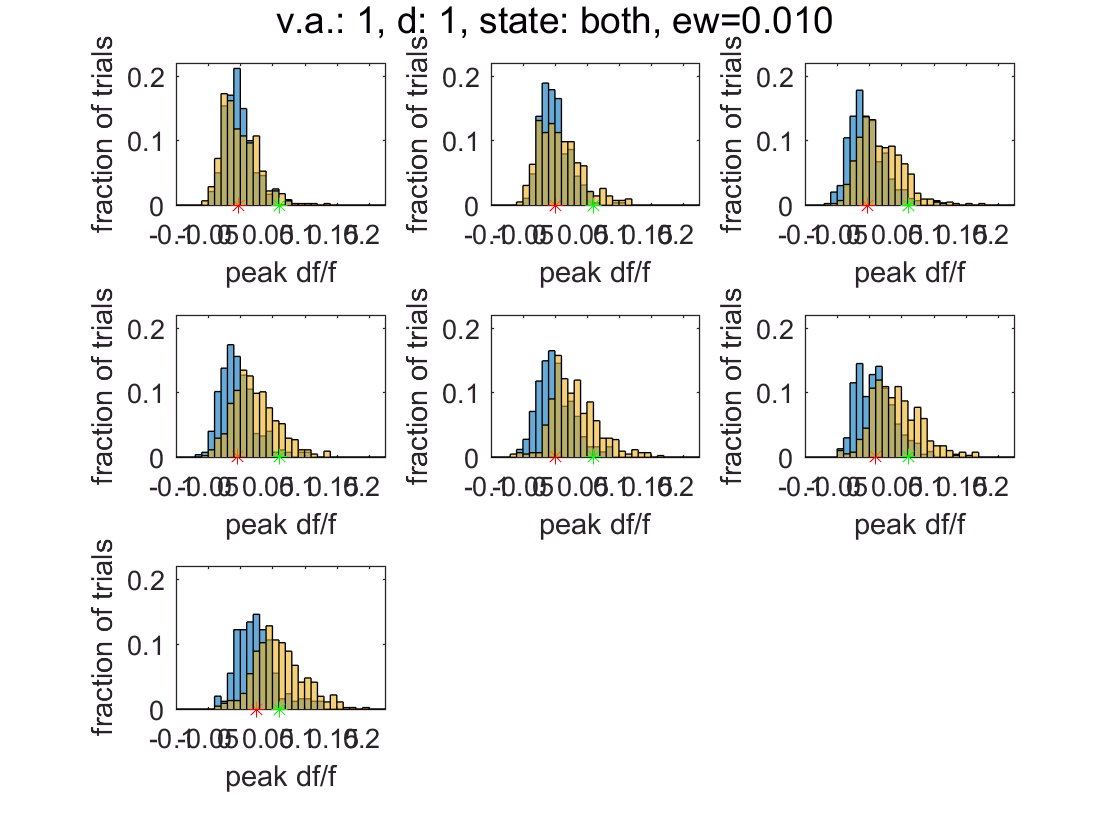


formatSpec = 'v.a.: %1.f, d: %1.f, state: %s, ew=%0.3f \n';
titleText = sprintf(formatSpec,visArea,durat,'both',edgeWidth);
suptitle(titleText)


clear d
for d = durat
    
    
    clear i
    for i = visArea
      
        clear lo_numTrialsAllSess_AllCons
        clear lo_sumTrialsAcrossSess_AllCons 
        
            
        clear c
        for c = cont
            
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
             
            
            clear n
            for n = sess
  
                % get values for 1st sesson, cth dth ith trials
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                % num trials this n this c
                lo_numTrialsAllSess_AllCons(n,c) = length(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                hi_numTrialsOneSessOneC(n,c) = length(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % COLLECT
            % for each sess, cth contrast, save num of trials at this contrast
            lo_sumTrialsAcrossSess_eachCon = sum(lo_numTrialsAllSess_AllCons(:,c));
            % COLLECTING
            lo_sumTrialsAcrossSess_AllCons(1,c) = lo_sumTrialsAcrossSess_eachCon;
            
            % PLOT one con at a time, all sess at once, each subplot
            
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(lo_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % COLLECT
            lo_mnDf_stat = mean(lo_dthithCthNth_pkDfEachTrial);
       
            y = 0;
        
            hold on
                
            % COLLECT
            lo_stdev_stat = (std(lo_dthithCthNth_pkDfEachTrial))/(sqrt(length(lo_sumTrialsEachCon_allSess)));
            
            h2 = scatter(lo_mnDf_stat,y,'*','r');
            
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,lo_sumNumTrialsEachCon_allSess));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            hold on  
            
            % COLLECT
            % for all sess, cth contrast, save num of trials at this contrast
            hi_sumTrialsEachCon_allSess = sum(hi_numTrialsOneSessOneC(:,c),1);
            
            % PLOT one con at a time, all sess at once, each subplot
            
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h3 = histogram(hi_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % COLLECT
            hi_mnDf_run = mean(hi_dthithCthNth_pkDfEachTrial);

            y = 0;
        
            hold on
                
            % COLLECT
            hi_stdev_run = (std(hi_dthithCthNth_pkDfEachTrial))/(sqrt(hi_sumTrialsEachCon_allSess));
            
            h4 = scatter(mnDf_run,y,'*','g');
            
            formatSpec = 'c=%s, mnS=%0.3f, stS=%0.3f, \n mnR=%0.3f, stR=%0.3f nT=%1.0f,%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf_stat,stdev_stat, mnDf_run,stdev_run,lo_sumTrialsEachCon_allSess,hi_sumTrialsEachCon_allSess));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            
            
        end % end c loop
        
    end % end i loop

end % end d loop

% for each contrast. plot 5 subplots - one for each visual area

%durat = 1:length(uniqueDurations);
durat = 1

%cont = 1:length(uniqueContrasts)
cont = 1

visArea = 1:length(groupRoundYpts{1})
%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3 % AL
%visArea = 4 % AM 
%visArea = 5 % control

sess = 1:nGroup
%sess = 1

yMax = 0.22;
yLimit = [0 yMax];

xMax = 0.225;
xMin = -0.1;
xLimit = [xMin xMax];

xTickRange = [xMin:0.05:xMax];
xTickLabelRange = [xMin:0.05:xMax];

edgeWidth = 0.01;
edges = [xMin xMin:edgeWidth:xMax xMax]
%numBins = 25;

% ONE contrast per Fig!

fig2 = figure

formatSpec = 'v.a.: %1.f, d: %1.f, state: %s, ew=%0.3f \n';
titleText = sprintf(formatSpec,visArea,durat,'both',edgeWidth);
suptitle(titleText)

clear d
for d = durat
    
    clear c
    for c = cont
          
        clear lo_dthithCthNth_pkDfEachTrial
        lo_dthithCthNth_pkDfEachTrial = []; 
    
        clear hi_dthithCthNth_pkDfEachTrial
        hi_dthithCthNth_pkDfEachTrial = [];
    
        clear lo_sumNumTrialsEachCon_allSess
        clear hi_sumNumTrialsEachCon_allSess
        
        clear i
        for i = visArea
                
            clear n
            for n = sess
  
                % get values for 1st sesson, cth dth ith trials
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                % num trials this n this c
                lo_numTrialsOneSessOneC(n,c) = length(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                hi_numTrialsOneSessOneC(n,c) = length(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % for all sess, cth contrast, save num of trials at this contrast
            lo_sumTrialsEachCon_allSess = sum(lo_numTrialsOneSessOneC(:,c));
            
            % PLOT one con at a time, all sess at once, each subplot
            
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(lo_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            clear mnDf
            mnDf_stat = mean(lo_dthithCthNth_pkDfEachTrial);
            clear y
            y = 0;
        
            hold on
                
            stdev_stat = (std(lo_dthithCthNth_pkDfEachTrial))/(sqrt(length(lo_sumTrialsEachCon_allSess)));
            
            h2 = scatter(mnDf_stat,y,'*','r');
            
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,lo_sumNumTrialsEachCon_allSess));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            hold on  
            
            % for all sess, cth contrast, save num of trials at this contrast
            hi_sumTrialsEachCon_allSess = sum(hi_numTrialsOneSessOneC(:,c));
            
            % PLOT one con at a time, all sess at once, each subplot
            
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(hi_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            clear mnDf
            mnDf_run = mean(hi_dthithCthNth_pkDfEachTrial);
            clear y
            y = 0;
        
            hold on
                
            stdev_run = (std(hi_dthithCthNth_pkDfEachTrial))/(sqrt(length(hi_dthithCthNth_pkDfEachTrial)));
            
            h2 = scatter(mnDf_run,y,'*','g');
            
            formatSpec = 'c=%s, mnS=%0.3f, stS=%0.3f, \n mnR=%0.3f, stR=%0.3f nT=%1.0f,%1.0f';
            title(sprintf(formatSpec,cons4axes{c},mnDf_stat,stdev_stat, mnDf_run,stdev_run,lo_sumTrialsEachCon_allSess,hi_sumTrialsEachCon_allSess));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
        end % end i loop
        
    end % end c loop

end % end d loop

